In this code, lets try to expand the feasible regions of local design and gobal design through local dynamic feedback control and global performance function trunction. 

Code for the global controller design (from temp2.mlx)

clear all
load tempNet.mat

obj = net.platoons(1)

obj =   Platoon with properties:

     platoonIndex: 1
    numOfVehicles: 4
         vehicles: [1×4 Vehicle]
         topology: [1×1 Topology]
         graphics: [30.4893 31.4893 32.4893 33.4893 34.4893 35.4893 36.4893]



% Number of follower vehicles
N = obj.numOfVehicles-1; 

% Creating the adgacency matrix, null matrix and cost matrix
G = obj.topology.graph;
A = adjacency(G);
for i = 1:1:N
    for j = 1:1:N
        % Structure of K_ij (which is a 3x3 matrix) should be embedded here
        if i~=j
            if A(i+1,j+1)==1
                adjMatBlock{i,j} = [0,0,0; 0,0,0; 1,1,1];
                nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
                costMatBlock{i,j} = 0.01*[0,0,0; 0,0,0; 1,1,1];
            else
                adjMatBlock{i,j} = [0,0,0; 0,0,0; 0,0,0];
                nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
                costMatBlock{i,j} = 1*[0,0,0; 0,0,0; 1,1,1];
            end
        else
            adjMatBlock{i,j} = [0,0,0; 0,0,0; 1,1,1];
            nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
            costMatBlock{i,j} = 100*[0,0,0; 0,0,0; 1,1,1];
        end
    end 
end
adjMatBlock = cell2mat(adjMatBlock)

adjMatBlock =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1


nullMatBlock = cell2mat(nullMatBlock)

nullMatBlock =      1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0


costMatBlock = cell2mat(costMatBlock)

costMatBlock =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
  100.0000  100.0000  100.0000    0.0100    0.0100    0.0100    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    0.0100    0.0100    0.0100  100.0000  100.0000  100.0000    0.0100    0.0100    0.0100
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100  100.0000  100.0000  100.0000



% Set up the LMI problem
solverOptions = sdpsettings('solver','mosek','verbose',0);
I = eye(3*N);
I_n = eye(3);
I_N = eye(N);
O = zeros(3*N);
O_N3N = zeros(N,3*N)

O_N3N =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0



%% 
isSoft = 1;

dataset = []


dataset =

     []



count = 1;
for gammaSqBar = 0.1:0.3:1.6
    for nu = -0.1:-0.5:-10.1 %-0.1:-0.2:-5 %-1:-5:-101
        for rho = 0.1:0.5:10.1 %0.1:0.2:5 %1:5:101
                        
            Q = sdpvar(3*N,3*N,'full'); 
            P = sdpvar(N,N,'diagonal');
            gammaSq = sdpvar(1,1,'full');
            
            C = []; %M_ze matrix
            X_p_11 = [];
            X_p_12 = [];
            X_12 = [];
            X_p_22 = [];
            for i = 1:1:N   
                C = [C; zeros(1,3*(i-1)),[0,1,0],zeros(1,3*(N-i))];
                X_p_11 = blkdiag(X_p_11,-nu*P(i,i)*I_n);
                X_p_12 = blkdiag(X_p_12,0.5*P(i,i)*I_n);
                X_12 = blkdiag(X_12,(-1/(2*nu))*I_n);
                X_p_22 = blkdiag(X_p_22,-rho*P(i,i)*I_n);
            end
            X_p_21 = X_p_12';
            X_21 = X_12';
            
            % Temporary: to consider z = e
            I_N = eye(3*N);  C = I_N;  O_N3N = O; 

            
            % Objective Function
            costFun = norm(Q.*costMatBlock,1);
            
            % Budget Constraints
            con0 = costFun <= 1;
            
            % Basic Constraints
            con1 = P >= 0;
            con2 = gammaSq >= 0;
            con3 = gammaSq <= gammaSqBar;
            con4 = trace(P)==1;
                        
            DMat = [X_p_11, O_N3N'; O_N3N, I_N];
            MMat = [Q, X_p_11; C, O_N3N];
            ThetaMat = [-X_21*Q-Q'*X_12-X_p_22, -X_p_21; -X_p_12, gammaSq*I];
            con5 = [DMat, MMat; MMat', ThetaMat] >= 0; % The real one
            
            % Structural constraints
            con6 = Q.*(nullMatBlock==1)==O;  % Structural limitations (due to the format of the control law)
            con7 = Q.*(adjMatBlock==0)==O;  % Graph structure : hard constraint
            
            % Total Cost and Constraints
            if isSoft
                cons = [con1,con2,con3,con5,con6]; % Without the hard graph constraint con7
                costFun = 1*costFun + 1*gammaSq; % soft 
            else
                cons = [con1,con2,con3,con4,con5,con6,con7]; % With the hard graph constraint con7
                costFun = 1*costFun + 1*gammaSq; % hard (same as soft)
            end
            
            sol = optimize(cons,[costFun],solverOptions);
%             status = sol.info;
            
%             PVal = value(P);
%             QVal = value(Q);
%             
%             costFunVal = value(costFun);
%             gammaSqVal = value(gammaSq);
%             
%             X_p_11Val = value(X_p_11);
%             X_p_21Val = value(X_p_21);
%             
%             M_neVal = X_p_11Val\QVal;
%            
%             % Obtaining K_ij blocks
%             M_neVal(nullMatBlock==1) = 0;
            
            % Data set collecting
            dataset = [dataset; sol.problem==0,gammaSqBar,nu,rho];
            count = count + 1
        end
    end
end

Plotting

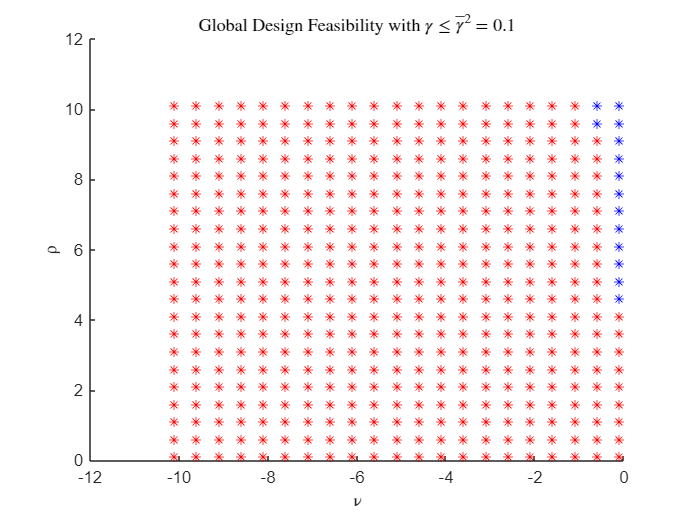

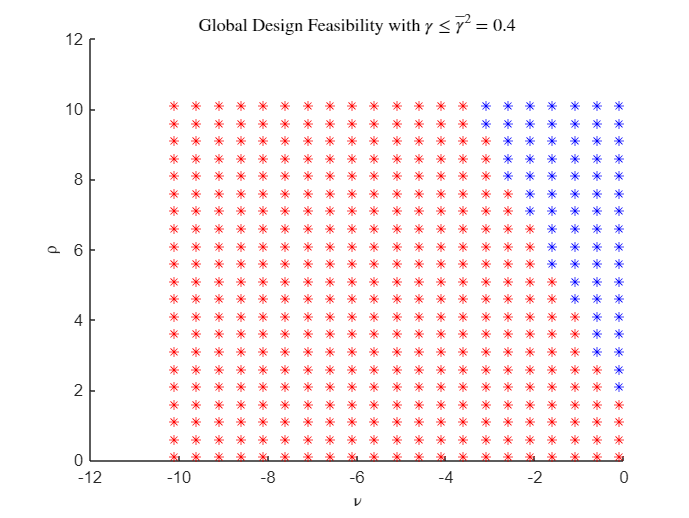

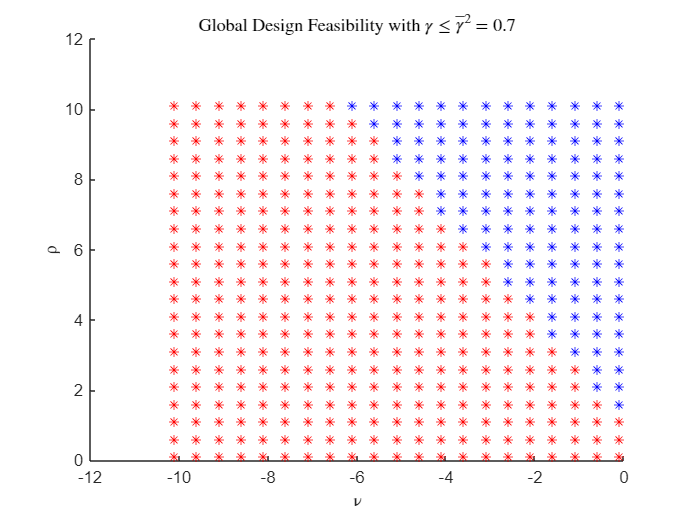

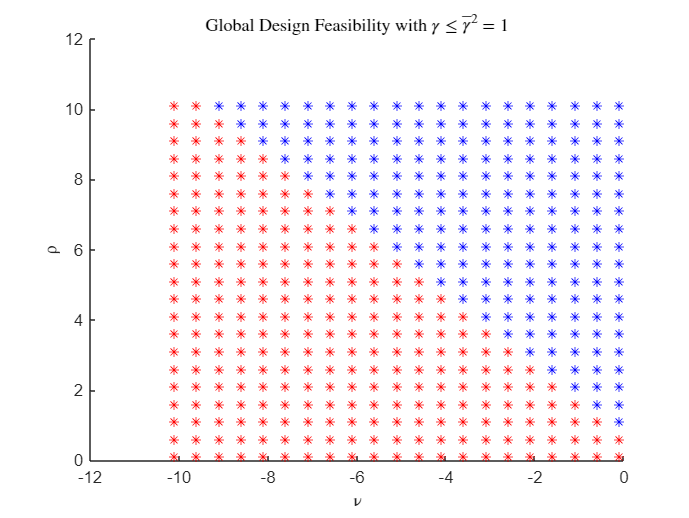

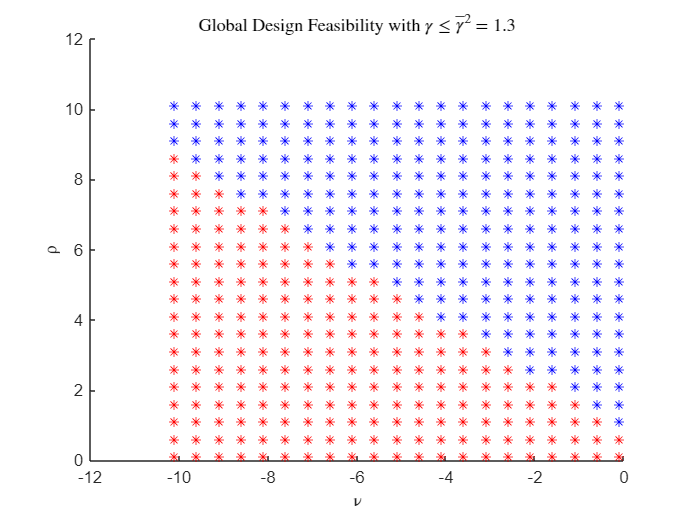

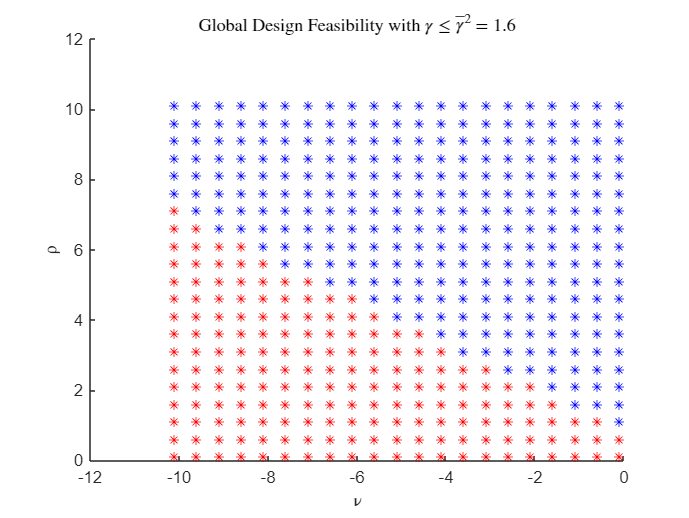

clear all
load dataset12.mat 
% dataset7.mat for N=3 and with reduced performance (position error)
% dataset8.mat for N=3 and with reduced performance (velocity error)
% dataset9.mat for N=3 and with reduced performance (acceleration error)
% dataset10.mat for N=3 and with reduced performance (acceleration error, without trace(p)=1)
% dataset11.mat for N=3 and with reduced performance (velocity error, without trace(p)=1)


success = dataset(:,1);
gammas = dataset(:,2);
nus = dataset(:,3);
rhos = dataset(:,4);

for gammaVal = 0.1:0.3:1.6

    successVals = success(gammas==gammaVal);
    nuVals = nus(gammas==gammaVal);
    rhoVals = rhos(gammas==gammaVal);
    
    figure
    hold on
    for i = 1:1:length(nuVals)
        if successVals(i) == 1
            plot(nuVals(i),rhoVals(i),'*b')
        else
            plot(nuVals(i),rhoVals(i),'*r')
        end
    end
    xlabel('\nu')
    ylabel('\rho')
    title(['Global Design Feasibility with $\gamma\leq\bar{\gamma}^2=$',num2str(gammaVal)], 'interpreter', 'latex')
    
end

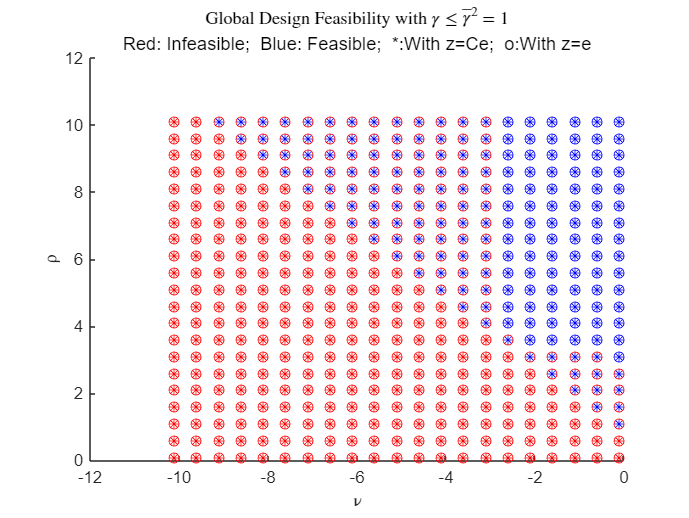


% Comparison
load dataset12.mat

success = dataset(:,1);
gammas = dataset(:,2);
nus = dataset(:,3);
rhos = dataset(:,4);

gammaVal = 1;
gammaValTest = abs(gammas-gammaVal)<0.001;

successVals = success(gammaValTest);
nuVals = nus(gammaValTest);
rhoVals = rhos(gammaValTest);

figure
hold on
for i = 1:1:length(nuVals)
    if successVals(i) == 1
        plot(nuVals(i),rhoVals(i),'*b')
    else
        plot(nuVals(i),rhoVals(i),'*r')
    end
end
xlabel('\nu')
ylabel('\rho')
title(['Global Design Feasibility with $\gamma\leq\bar{\gamma}^2=$',num2str(gammaVal)], 'interpreter', 'latex')


load dataset5.mat
success = dataset(:,1);
gammas = dataset(:,2);
nus = dataset(:,3);
rhos = dataset(:,4);

gammaValTest = abs(gammas-gammaVal)<0.001;

successVals = success(gammaValTest);
nuVals = nus(gammaValTest);
rhoVals = rhos(gammaValTest);
    
for i = 1:1:length(nuVals)
    if successVals(i) == 1
        plot(nuVals(i),rhoVals(i),'ob')
    else
        plot(nuVals(i),rhoVals(i),'or')
    end    
end

% load dataset5L.mat
% success = datasetL(:,1);
% nus = datasetL(:,2);
% rhos = datasetL(:,3);
% costs = datasetL(:,4);
% 
% hold on
% for i = 1:1:length(nus)
%     if success(i) == 1
%         plot(nus(i),rhos(i),'^b')
%     else
% %         plot(nus(i),rhos(i),'^r')
%     end
% end
subtitle('Red: Infeasible;  Blue: Feasible;  *:With z=Ce;  o:With z=e')

Local Design Problem (Dynamic Output Feedback controller)

clear all

% Local Error Dynamics
A = [0,1,0;0,0,1;0,0,0];
B = [0;0;1];
I = eye(3);
O = zeros(3);

% Set up the LMI problem
solverOptions = sdpsettings('solver','mosek','verbose',0);

datasetL = [];
count = 1;

for nuVal = -0.1:-0.5:-10.1 %-0.1:-0.2:-5 %-1:-5:-101
    for rhoVal = 0.1:0.5:10.1 %0.1:0.2:5 %1:5:101

        rhoBar = sdpvar(1,1,'full'); %Representing: 1/rho
        nu = sdpvar(1,1,'full');
        X = sdpvar(3,3,'symmetric'); 
        Y = sdpvar(3,3,'symmetric');

        An = sdpvar(3,3,'full');
        Bn = sdpvar(3,3,'full');
        Cn = sdpvar(1,3,'full');
        Dn = sdpvar(1,3,'full');

        % Basic Constraints        
        con1 = X >= 0;
        con2 = Y >= 0;
        con3 = [Y, I; I, X] >= 0;

        c1 = -A*Y-B*Cn;
        c2 = -A-An'-B*Dn;
        c3 = -X*A-Bn;
        DMat = [rhoBar*I];
        MMat = [Y, I, O];
        ThetaMat = [c1+c1', c2, -I+0.5*Y; c2', c3+c3', -X+0.5*I; -I+0.5*Y, -X+0.5*I, -nu*I];
        W = [DMat, MMat; MMat', ThetaMat];
        con4 = W >= 0;

        % Some modesty constraints on resulting nu and rho from the local design
        con5 = nu == nuVal;
        con6 = rhoBar == 1/rhoVal;

        % Total Cost and Constraints
        cons = [con1,con2,con3,con4,con5,con6];
        costFun = nu+rhoBar;

        % Solution
        sol = optimize(cons,[costFun],solverOptions);
            
        XVal = value(X);
        YVal = value(Y);
        AnVal = value(An);
        BnVal = value(Bn);
        CnVal = value(Cn);
        DnVal = value(Dn);
        [M,N] = lu(I-XVal*YVal); % controller parameters
        N = N';
        Ac = M\(AnVal-BnVal*C*YVal-XVal*B*CnVal-XVal*(A-B*DnVal*C)*YVal)/(N');
        Bc = M\(BnVal-XVal*B*DnVal);
        Cc = (CnVal-DnVal*C*YVal)/(N');
        Dc = DnVal;
        Abar = [A+B*Dc*C, B*Cc; Bc*C, Ac]; %closed loop system
        
        status = sol.info;
        datasetL = [datasetL; sol.problem==0, nuVal, rhoVal, value(costFun)];
        count = count + 1
    end
end     

Plotting feasible and infeasible nu,rho combinations

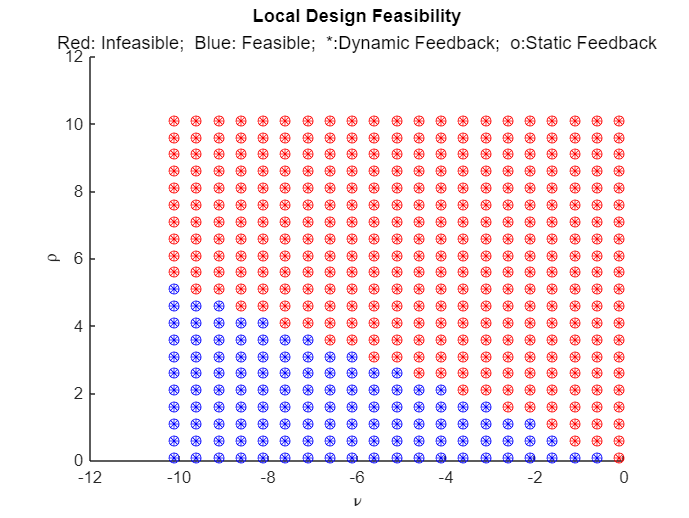

clear all
close all

load dataset7L.mat % dataset
success = datasetL(:,1);
nus = datasetL(:,2);
rhos = datasetL(:,3);
costs = datasetL(:,4);


figure
hold on
for i = 1:1:length(nus)
    if success(i) == 1
        plot(nus(i),rhos(i),'*b')
    else
        plot(nus(i),rhos(i),'*r')
    end
end
xlabel('\nu')
ylabel('\rho')
title('Local Design Feasibility')

load dataset5L.mat
success = datasetL(:,1);
nus = datasetL(:,2);
rhos = datasetL(:,3);
costs = datasetL(:,4);

for i = 1:1:length(nus)
    if success(i) == 1
        plot(nus(i),rhos(i),'ob')
    else
        plot(nus(i),rhos(i),'or')
    end
end
xlabel('\nu')
ylabel('\rho')
title('Local Design Feasibility')

subtitle('Red: Infeasible;  Blue: Feasible;  *:Dynamic Feedback;  o:Static Feedback')

A = obj.networkMatrices.A;
B = obj.networkMatrices.B;
C = obj.networkMatrices.C;
D = obj.networkMatrices.D;
E = obj.networkMatrices.E;
F = obj.networkMatrices.F;
if isequal(dissFrom,'w') % the only possibility under DOF
    if isequal(dissTo,'y')
        G = obj.networkMatrices.C;
        H = obj.networkMatrices.D;
        J = obj.networkMatrices.F;                    
    elseif isequal(dissTo,'z')
        G = obj.networkMatrices.G;
        H = obj.networkMatrices.H;
        J = obj.networkMatrices.J;
    end
end
if sum(sum(abs(D)))~=0
    disp('System matrix D is not null!')
    return
end
n = size(A,1);
% p = size(B,2);
% q = size(C,1);

% Y = diag(sdpvar(n,1));
% X = diag(sdpvar(n,1));
% An = sdpvar(n,n,'full');
% Bn = sdpvar(n,q);
% Cn = sdpvar(p,n);
% Dn = sdpvar(p,q);            
X = []; Y = [];
An = []; Bn = []; Cn = []; Dn = [];
for i = 1:1:length(obj.subsystems)
    n_i = obj.subsystems(i).dim_n;
    p_i = obj.subsystems(i).dim_p;
    X = blkdiag(X,sdpvar(n_i,n_i));
    Y = blkdiag(Y,sdpvar(n_i,n_i));
    An_i = []; Bn_i = []; Cn_i = []; Dn_i = [];
    for j = 1:1:length(obj.subsystems)
        n_j = obj.subsystems(j).dim_n;
        p_j = obj.subsystems(j).dim_p;
        m_j = obj.subsystems(j).dim_m;                    
        if any(obj.neighbors{i}==j)
            An_i = [An_i, sdpvar(n_i,n_j,'full')];
            Bn_i = [Bn_i, sdpvar(n_i,m_j,'full')];
            Cn_i = [Cn_i, sdpvar(p_i,n_j,'full')];
            Dn_i = [Dn_i, sdpvar(p_i,m_j,'full')];
        else
            An_i = [An_i, zeros(n_i,n_j)];
            Bn_i = [Bn_i, zeros(n_i,m_j)];
            Cn_i = [Cn_i, zeros(p_i,n_j)];
            Dn_i = [Dn_i, zeros(p_i,m_j)];
        end
    end
    An = [An; An_i]; Bn = [Bn; Bn_i]; Cn = [Cn; Cn_i]; Dn = [Dn; Dn_i];
end


I = eye(n);
con1 = X >= 0;
con2 = Y >= 0;
con3 = [Y, I; I, X] >= 0;
c1 = -A*Y-B*Cn;
c2 = -A-B*Dn*C-An';
c3 = -E-B*Dn*F+(Y*G'+Cn'*H')*S;
c4 = Y*G'+Cn'*H';
c5 = -X*A-Bn*C;
c6 = -X*E-Bn*F+(G'+C'*Dn'*H')*S;
c7 = G'+C'*Dn'*H';
c8 = (J'+F'*Dn'*H')*S+S'*(J+H*Dn*F)+R;
c9 = J'+F'*Dn'*H';
if all(Q(:)==0)
    con4 = [c1+c1', c2, c3; c2', c5+c5', c6; c3', c6', c8]>=0;
else
    con4 = [c1+c1', c2, c3, c4; c2', c5+c5', c6, c7; c3', c6', c8, c9; c4', c7', c9', -inv(Q)]>=0;
end 
sol = optimize([con1,con2,con3,con4],[],solverOptions);
isDOFDissipative = sol.problem==0;
XVal = value(X);
YVal = value(Y);
AnVal = value(An);
BnVal = value(Bn);
CnVal = value(Cn);
DnVal = value(Dn);
[M,N] = lu(I-XVal*YVal); % controller parameters
N = N';
Ac = M\(AnVal-BnVal*C*YVal-XVal*B*CnVal-XVal*(A-B*DnVal*C)*YVal)/(N');
Bc = M\(BnVal-XVal*B*DnVal);
Cc = (CnVal-DnVal*C*YVal)/(N');
Dc = DnVal;
Abar = [A+B*Dc*C, B*Cc; Bc*C, Ac]; %closed loop system

%             Bbar = [E+B*Dc*F;Bc*F];
%             Cbar = [G+H*Dc*C, H*Cc];
%             Dbar = [J+H*Dc*F];
%             eigs = eig(Abar)